clear; clc; close all;
% 严格使用你提供的正确文件路径
data1 = load("D:\GitHub\Matlab\波形图\waves.mat");
data = data1.waves;
outputPath = 'D:\同步\毕业设计\毕业设计\毕业论文\Figure\Waves';
if ~exist(outputPath, 'dir'), mkdir(outputPath); end
x = data.x_BLB_X;
y = [data.x_I_SRAM_Q_Y data.x_I_SRAM_QB_Y data.x_BL_Y data.x_BLB_Y ...
     data.x_I_VSA_Q_Y data.x_I_VSA_QB_Y data.x_CLK_Y data.x_WL_Y ...
     data.x_WR_Y data.x_IN_Y data.x_R_Y];

time_markers = [5,10,15,20,25]*1e-9;
stage_labels = {'保持','写0','读0','写1','读1'};
stage_centers = [3.75,7.5,12.5,17.5,22.5]*1e-9;

% 创建图形并设置渲染器（解决matlab2tikz文字消失问题）
figure('Position', [100, 100, 1000, 800]);
set(gcf, 'renderer', 'painters');

% 上子图：Q和QB
subplot(2,1,1);
p1 = plot(x, y(:,1), 'b-', 'LineWidth', 1.5); hold on;
p2 = plot(x, y(:,2), 'r-', 'LineWidth', 1.5);
grid on;
ylabel('Voltage (V)');
xlim([2.5e-9, 28e-9]);
ylim([-0.1, 0.8]);

% 下子图：BL和BLB
subplot(2,1,2);
p3 = plot(x, y(:,3), 'g-', 'LineWidth', 1.5); hold on;
p4 = plot(x, y(:,4), 'm-', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Voltage (V)');
xlim([2.5e-9, 28e-9]);
ylim([-0.1, 0.8]);

% 统一图例（完全保留你设置的位置）
subplot(2,1,1);
lh = legend([p1,p2,p3,p4], {'Q','QB','BL','BLB'});
lh.Position = [0.0541 0.4826 0.0779 0.0786];
lh.AutoUpdate = 'off';

% 上子图：灰色虚线+阶段文字
y_max = 0.8;
for i = 1:length(time_markers)
    xline(time_markers(i), 'Color', [0.5 0.5 0.5], 'LineStyle', '--', ...
          'LineWidth', 1, 'Alpha', 0.5, 'HandleVisibility', 'off');
end
for i = 1:length(stage_labels)
    text(stage_centers(i), y_max*1.08, stage_labels{i}, ...
         'HorizontalAlignment', 'center', 'FontSize', 10, ...
         'FontWeight', 'bold', 'HandleVisibility', 'off');
end

% 下子图：仅灰色虚线，无文字
subplot(2,1,2);
for i = 1:length(time_markers)
    xline(time_markers(i), 'Color', [0.5 0.5 0.5], 'LineStyle', '--', ...
          'LineWidth', 1, 'Alpha', 0.5, 'HandleVisibility', 'off');
end

set(gcf, 'color', 'w');

% ===================== 修正后的matlab2tikz导出命令 =====================
% 严格使用你提供的文件名和参数，添加关键参数解决导出问题
% matlab2tikz(fullfile(outputPath, 'wave_Q_QB_BL_BLB.tex'), ...
%     'showInfo', false, ...
%     'parseStrings', false, ...
%     'strictFontSize', true);
disp('✓ wave_Q_QB_BL_BLB.tex 已生成');

✓ wave_Q_QB_BL_BLB.tex 已生成


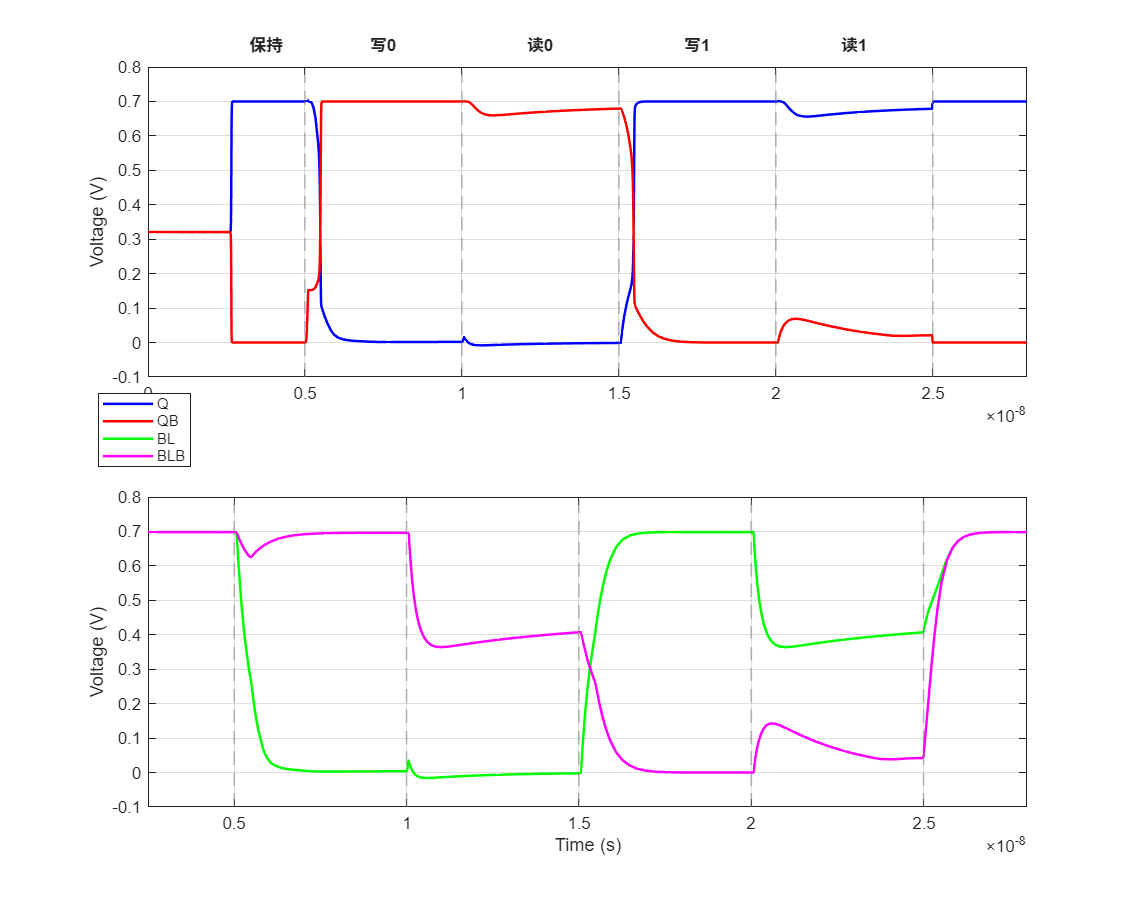

% ===================== 新增：放大图（0 ~ 0.6 ns） =====================
figure('Position', [100, 100, 1000, 800]);
set(gcf, 'renderer', 'painters');

% 上子图：Q 和 QB
subplot(2,1,1);
plot(x, y(:,1), 'b-', 'LineWidth', 1.5); hold on;
plot(x, y(:,2), 'r-', 'LineWidth', 1.5);
grid on;
ylabel('Voltage (V)');
xlim([2.5e-9, 6e-9]);          % 横坐标放大范围：0 ~ 0.6 ns
ylim([-0.1, 0.8]);

% 下子图：BL 和 BLB
subplot(2,1,2);
plot(x, y(:,3), 'g-', 'LineWidth', 1.5); hold on;
plot(x, y(:,4), 'm-', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Voltage (V)');
xlim([2.5e-9, 6e-9]);          % 横坐标放大范围：0 ~ 0.6 ns
ylim([-0.1, 0.8]);

% 统一图例（放置于左上角，可自行调整位置）
subplot(2,1,1);
lh = legend([p1,p2,p3,p4], {'Q','QB','BL','BLB'}, 'Location', 'northwest');
lh.AutoUpdate = 'off';


subplot(2,1,1)
legend(["Q", "QB", "BL", "BLB"], "AutoUpdate", "off", "Location", "none", "Position", [0.0910 0.4787 0.0817, 0.0825])

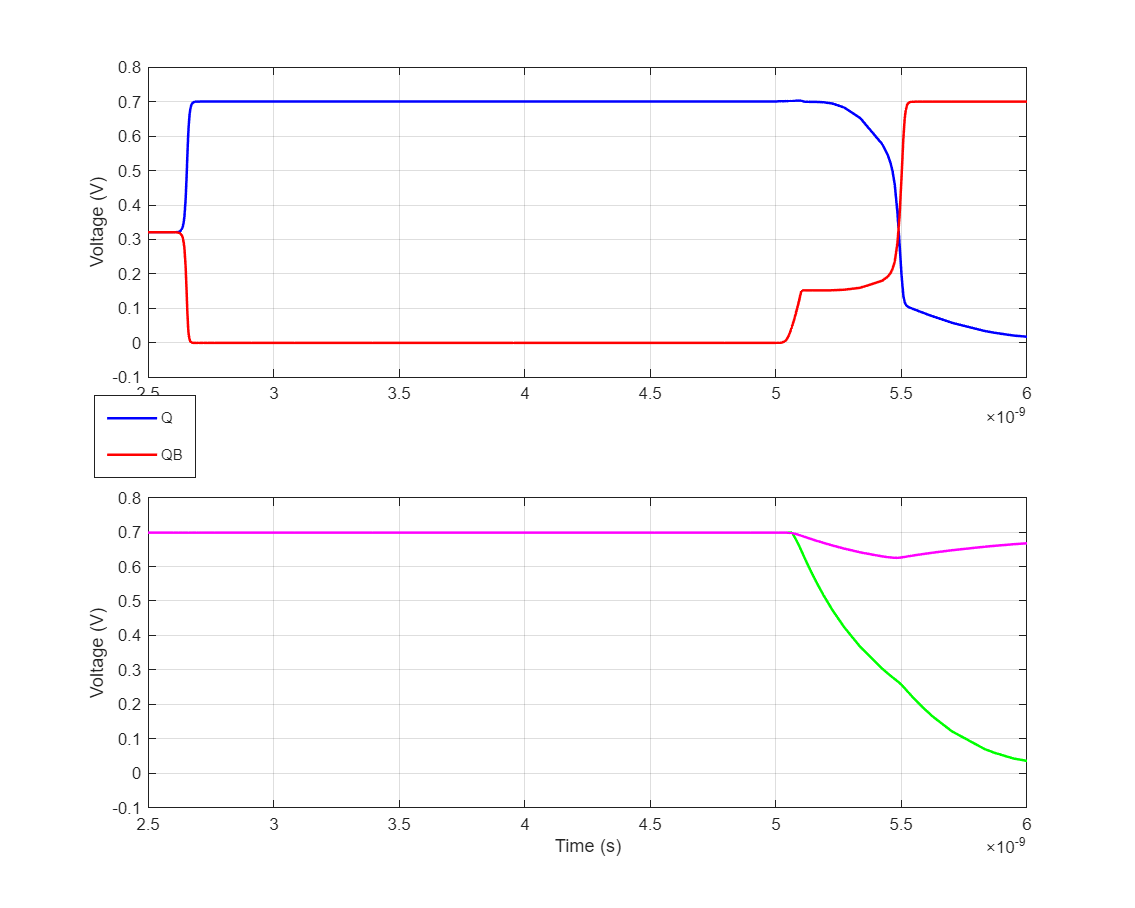


subplot(2,1,1)
legend(["Q", "QB", "BL", "BLB"], "AutoUpdate", "off", "Location", "none", "Position", [0.0866 0.4776 0.0817, 0.0825])

% title('Zoomed view: 0 to 0.6 ns');   % 可选标题，便于区分

set(gcf, 'color', 'w');